# Position Control

After looking at attitude control, we can cascade  velocity and position controllers to provide the attitude setpoints. The position controller outputs velocity commands to the velocity controller, which in turn provide thrust vector command. The thrust command is transformed to attitude setpoint and fed to attitude controller. Finally the attitude controller outputs rates commands to the rates controller which feeds torques and thrust values to the mixer and motor controllers.

## Position control

- P controller only

- Output  is fed as velocity set point to velocity controllers

- Output is limited by maximum allowed velocity


$$V_{\textrm{sp}} =\left\lbrack \begin{array}{c}
k_{\textrm{px}} \\
k_{\textrm{py}} \\
k_{\textrm{pz}} 
\end{array}\right\rbrack \left(\left\lbrack \begin{array}{c}
x_c \\
y_c \\
z_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack \right)$$


## Velocity control

- `Output is the thrust setpoint vector `$T_{\textrm{sp}}$

- `Hover thrust (-m*g) is sent as a Feed-Forward term, in order to ``allow hover when the position and velocity error are zero`

- `Desired acceleration (`${\textrm{Acc}}_{\textrm{sp}}$`) is also a feed-forward term`

- `Vertical velocity controller gain is different from horizontal (xy) velocity controllers`

- `For practical implementations, the D term is negative-multipled by the acceleration rather than error in velocity`

- `For practical implementations, the I term is clipped to avoid winding.`


$$T_{\mathrm{sp}} =\mathrm{PID}\left(\left\lbrack \begin{array}{c}
v_{\mathrm{xc}} \\
v_{\mathrm{yc}} \\
v_{\mathrm{zc}} 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack \right)+{g*\mathrm{Acc}}_{\mathrm{sp}} +\left\lbrack \begin{array}{c}
0\\
0\\
-m\ldotp g
\end{array}\right\rbrack$$


### Limiting tilt angle by saturating horizontal thrust

- The horizontal thrust must be limited according to the maximum allowed tilt angle $\alpha$. Maximum tilt angle is user defined and depends on the drone hardware, weight and size.

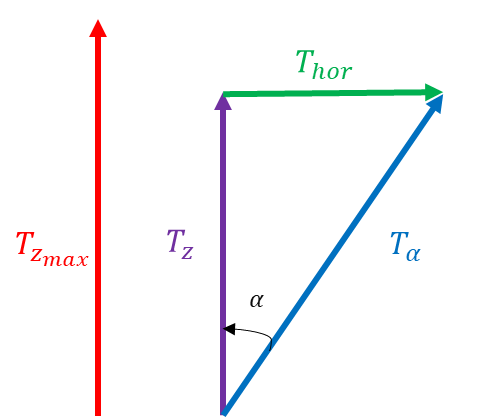

- $T_{z_{\max } }$ is max thrust the drone can produce 

- α is maximum allowed tilt angle

- Thrust setpoint from velocity control is (Tx,Ty, Tz) 

- **Saturate** **the** **horizontal****thrust setpoints as follow:**

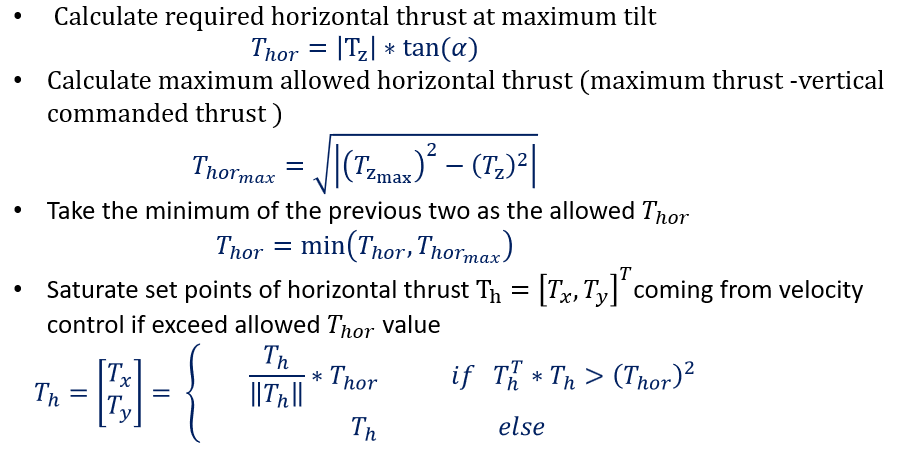

## Thrust and yaw to attitude set point 

The thrust vector set point coming from velocity controller along with yaw set point need to be converted to an attitude set point for the attitude controller.

- We will look into this conversion for quaternion-based attitude controller.

- This is adapted from PX4 implementation.

- The idea is to poject the thrust vector towards the target position and get the rotation matrix. The rotation matrix is then converted into a quaternion setpoint.

- This projection is for the horizontal components. Vertical thrust equals to the magnitude of the thrust vector.

**the procedure is as follows:**

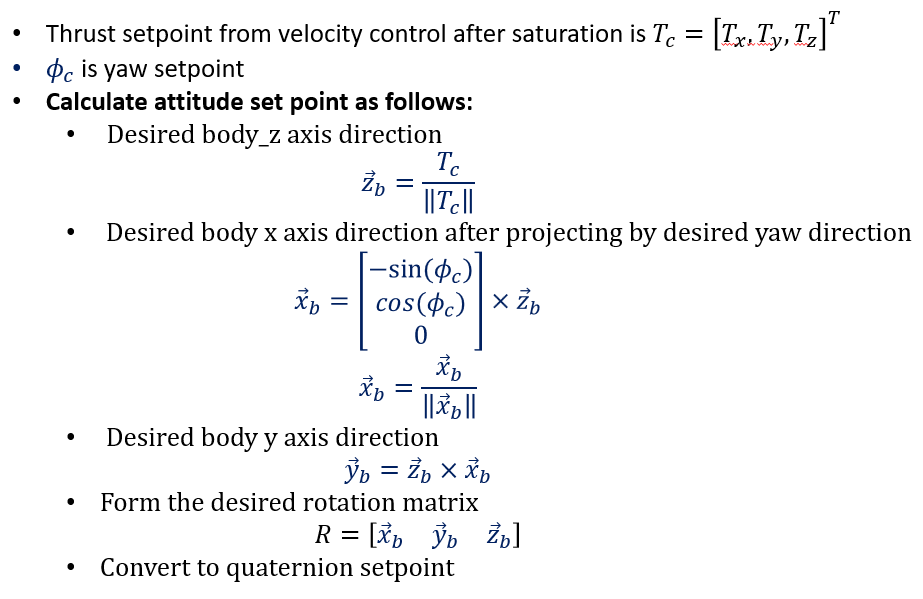

# Simulations

## Drone parameters

clear all;
run("quad_params.m")

## Full control simulations

open_system("position_control.slx")

## References

Quaternion based Estimation and Control for Attitude Tracking of a Quadcopter using IMU sensors, Matthias Grob  2016

PX4 control, [https://docs.px4.io/main/en/flight_stack/controller_diagrams.html](https://docs.px4.io/main/en/flight_stack/controller_diagrams.html)